# COP507 Computer Vision 2021/22 Assignment Specification

# By Siddharth Shaligram (#F114060)

clc
close all

% mkdir trainingData benign
% mkdir trainingData malignant
%
% nMalignant = 20;
% iMalignant = 0;
% nBenign = 20;
% iBenign = 0;
% gtruth = fopen("groundtruth.csv");
% while ~feof(gtruth)
%     l1 = fgetl(gtruth);
%     l1 = split(l1,",");
%     im = imread("lesionimages/" + l1(1) + ".jpg");
%     if strcmp(l1(2),'malignant')
%         if iMalignant < nMalignant
%             imwrite(im,"trainingData/" + l1(2) + "/"+l1(1) + ".jpg");
%         end
%         iMalignant = iMalignant + 1;
%     elseif strcmp(l1(2),'benign')
%         if iBenign < nBenign
%             imwrite(im,"trainingData/" + l1(2) + "/"+l1(1) + ".jpg");
%         end
%         iBenign = iBenign + 1;
%     end
% end

## Read all the Images

% Create Datastore of images
lesion_imds = imageDatastore("lesionimages/",'FileExtensions','.jpg');
mask_imds = imageDatastore("masks/","FileExtensions",".png");
% Read all images from a Datastore
lesion_imgs = readall(lesion_imds);
masks_imgs = readall(mask_imds);
% Display all imgs in grid
% imshow(imtile(lesion_imgs));
% imshow(imtile(masks_imgs));
% ref: https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html

## Read ground truth CSV file

csv_grdth = readmatrix('groundtruth.csv','OutputType','string');
% Assign labels to lesions and masks
lesion_imds.Labels = csv_grdth(:,2);
mask_imds.Labels = csv_grdth(:,2);
% ref: https://uk.mathworks.com/help/matlab/ref/readmatrix.html

## Adjuesting the brightness and contrast

for i = 1:length(lesion_imgs)
    brt_img = lesion_imgs{i}+50;        %increase brightness by a constant 50
    gry_img = rgb2gray(lesion_imgs{i}); % convert rgb to grayscale
    const_img = imadjust(gry_img);  % increase contrast
end

## Extract Lesions from their background using masks

mkdir trainingData

folder_path = '/Users/siddharthshaligram/MATLAB/Projects/21cop507/Coursework/trainingData'

folder_path = '/Users/siddharthshaligram/MATLAB/Projects/21cop507/Coursework/trainingData'

for i = 1:length(lesion_imgs)
    tumor_bkg = imcomplement(masks_imgs{i}); % create complement of mask
    tumor = lesion_imgs{i} - tumor_bkg; %substract complement from lesion to remove bakground
    tumor = imresize(tumor,[512,512]); % Resize image to 512x512
    tumor = rgb2gray(tumor); % convert rgb to
    img_name = csv_grdth{i} + ".jpg";
    imwrite(tumor,fullfile(folder_path,img_name));
end

train_imds = imageDatastore("trainingData/",'FileExtensions','.jpg');
train_imgs = readall(train_imds);
% Assign labels to lesions and masks
train_imds.Labels = csv_grdth(:,2);

## Split the Datasets into training and testing at random

% x = training | y = testing
% Lesions
[x_lesionSet,y_lesionSet] = splitEachLabel(train_imds,0.80,"randomized");
% Read all the variables
x_lesion = readall(x_lesionSet); % lesion training set - 80%
x_lesion_lbl = x_lesionSet.Labels

x_lesion_lbl = 160×1 cell array
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }


y_lesion = readall(y_lesionSet); % lesion testing set 
y_lesion_lbl = y_lesionSet.Labels

y_lesion_lbl = 40×1 cell array
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}


% Masks
[x_maskSet,y_maskSet] = splitEachLabel(mask_imds,0.80,"randomized");
x_masks = readall(x_maskSet); % masks training set - 80%
x_masks_lbl = x_maskSet.Labels

x_masks_lbl = 160×1 cell array
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'malignant'}


y_masks = readall(y_maskSet); % masks testing set
y_masks_lbl = y_maskSet.Labels

y_masks_lbl = 40×1 cell array
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'benign'   }
    {'malignant'}
    {'malignant'}
    {'malignant'}
    {'malignant'}


# **Feature Extraction**

**Applying feature extraction on both training and testig data to retrieve parameters for classification**

## **ABCDEs of M**elanoma

% Asymmetry - 
% Training
for i = 1:length(x_lesion)
    im_edge = edge(x_lesion{i}, 'sobel');
    sh = logical(im_edge);
    fh = bwconncomp(sh);
    s = regionprops(fh,'MajorAxisLength','MinorAxisLength');
    
    astry_major = cat(1,s.MajorAxisLength);
    astry_minor = cat(1, s.MinorAxisLength);
    
    astry_major = astry_major(1,:);
    astry_minor = astry_minor(1,:);
   

    x_asym(i,1) = astry_minor + astry_major/ 2 * astry_minor + astry_major; 
    x_diameter(i,1) = astry_major * 25.4 / 1920;
end

% Testing
for i = 1:length(y_lesion)
    im_edge = edge(y_lesion{i}, 'sobel');
    sh = logical(im_edge);
    fh = bwconncomp(sh);
    s = regionprops(fh,'MajorAxisLength','MinorAxisLength');
    astry_minor = cat(1, s.MinorAxisLength);
    astry_major = cat(1,s.MajorAxisLength);
    astry_minor = astry_minor(1,:);
    astry_major = astry_major(1,:);

    y_asym(i,1) = astry_minor + astry_major/ 2 * astry_minor + astry_major; 
    y_diameter(i,1) = astry_major * 25.4 / 1920;
end

## Local Binary Pattern : Matlab LBP & Rotational Invariance LBP

% LBP function
conv_rilbp();
% Using rotational invariance LBP function
x_LBF_feature = [];
y_LBF_feature = [];
for i=1:length(x_lesion)
    x_LBF_feature(i,:) = mainHistImg(x_lesion{i});
end

for i=1:length(y_lesion)
    y_LBF_feature(i,:) = mainHistImg(y_lesion{i});
end

% Extracting Local Binary Pattern : https://uk.mathworks.com/help/vision/ref/extractlbpfeatures.html
x_LBP_features = [];
y_LBP_features = [];
for i = 1:length(x_lesion)
    x_LBP_features(i,:) = extractLBPFeatures(x_lesion{i}, "Upright", true);
end

for i = 1:length(y_lesion)
    y_LBP_features(i,:) = extractLBPFeatures(y_lesion{i}, "Upright", true);
end

## Bag of Features

[x_BOFSet,y_BOFSet] = splitEachLabel(train_imds,0.20,"randomized");
% Bag of Features identifies the features of each image catagory present
BOF = bagOfFeatures(x_BOFSet,"Verbose",true);

Creating Bag-Of-Features.
-------------------------
* Image category 1: benign
* Image category 2: malignant
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 40 images...done. Extracted 655360 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 524288
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 24/100 iterations (~1.49 seconds/iteration)...converged in 24 iterations.

* Finished creating Bag-Of-Features



%Train Image Catagory Classifier with training set and BOF
categoryClassifier = trainImageCategoryClassifier(x_BOFSet,BOF);

Training an image category classifier for 2 categories.
--------------------------------------------------------
* Category 1: benign
* Category 2: malignant

* Encoding features for 40 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



% Evaluate Clasification with confusion matrix
conf_Matrix = evaluate(categoryClassifier,y_lesionSet)

Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: benign
* Category 2: malignant

* Evaluating 40 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                    PREDICTED
KNOWN        | benign   malignant   
------------------------------------
benign       | 0.05     0.95        
malignant    | 0.05     0.95        

* Average Accuracy is 0.50.



conf_Matrix =     0.0500    0.9500
    0.0500    0.9500


mean(diag(conf_Matrix)) % Average Accuracy

ans = 0.5000

## Image Classification

% Creating arrays of features for training and testing of SVM
trainig_Features = [x_LBF_feature,x_LBP_features,x_asym,x_diameter]; % x_LBF_feature
testing_Features = [y_LBF_feature, y_LBP_features,y_asym,y_diameter]; % y_LBF_feature

% Train the model with training image data 
model = fitcsvm(trainig_Features, x_masks_lbl); 
full_crs_model = crossval(model);
mdl_pred = kfoldPredict(full_crs_model); 


[x_conf_mat ,order] = confusionmat(x_masks_lbl, mdl_pred ) 

x_conf_mat =     33    47
    36    44


order = 2×1 cell array
    {'benign'   }
    {'malignant'}


% print("Confusion Matrix = ")
x_conf_mat

x_conf_mat =     33    47
    36    44


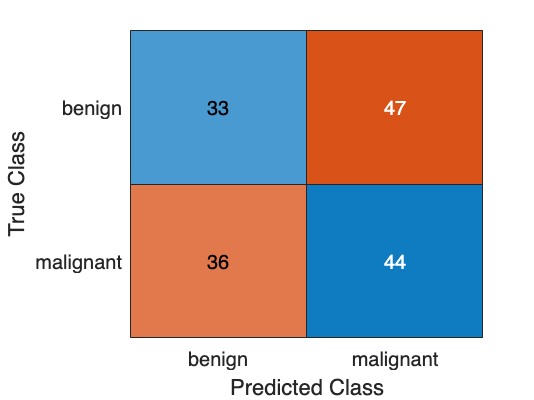

confusionchart(x_masks_lbl, mdl_pred) 

% Model accuracy
x_accuracy = sum(strcmpi(x_lesion_lbl, mdl_pred), 'all') / numel(mdl_pred); 
% print("accuracy = ")
x_accuracy

x_accuracy = 0.4688

## Final Predictions

% Calculate test/prediction accuracy. 
y_pred_mdl = predict(model, testing_Features); 

y_acc_mdl = sum(strcmpi(y_lesion_lbl, y_pred_mdl), 'all') / numel(y_pred_mdl); 
 
% Evaluate Model using accuracy, precision, and recal metrics. 
TN = x_conf_mat(1,1); 
TP = x_conf_mat(2,2); 
FN = x_conf_mat(1,2); 
FP = x_conf_mat(2,1);

recall = TP/(TP+FN);  
precision = TP/TP+FP; 

y_acc_mdl

y_acc_mdl = 0.4500

recall

recall = 0.4835

precision

precision = 37

### rotational invariance LBP Functions

function conv_rilbp 
% Table for mapping LBP coordinates to the rotation invariant LBP. 
    for i=0:255 
        cords = []; 
        cords(8) = i; 
        for j=1:7 
            cords(j) = bitRightRotate(i, j); 
        end 
        tab(i+1) = min(cords); 
    end 
    tab_unq = unique(tab); 
    
    for i=1:256 
        lbp_lktable = find(tab_unq==tab(i))-1; 
    end 
    
    lbp_lktable = lbp_lktable + 1; 
    save('lbp_lktable','lbp_lktable'); 
end

function hist = mainHistImg(image)
    % Calculate rotation invariant LBP.
    % first calculate normal LBP, than map to rotation invariant
    load("/Users/siddharthshaligram/MATLAB/Projects/21cop507/Coursework/lbp_lktable.mat"); 
    lhist = lbphist(image);
    hist = zeros(max(lbp_lktable),1);
    for i=1:length(lbp_lktable)
        hist(lbp_lktable(i)) = hist(lbp_lktable(i)) + lhist(i);
    end
end

% function hist = lbphist(image)
%     %calculate LBP histogram of Image
%     weight_matrix = [16 8 4;32 0 2; 64 128 1];
%     image_lbp = zeros(size(image,1)-2,size(image,2)-2);
%     for i=2:size(image,1)
%         for j=2:size(image,2)-1
%             block = image(i-1:i+1,j-1:j+1); % our 3x3
%             blockind = block>=block(2,2); % threshold by centre pixel and identify 1s
%             lbpcode = sum(weight_matrix(blockind));
%             image_lbp(i-1,j-1) = lbpcode;
%         end
%     end
%     hist = imhist(uint8(image_lbp), 256); % calculate the LBP histogram
%     hist = hist / sum(hist); % normalise histogram
% end

function hist = lbphist(image) 
    % Calculate LBP histogram of respective images.
    weight_matrix = [16 8 4; 32 0 2; 64 128 1];
    image_lbp = zeros(size(image,1)-2, size(image,2)-2);
    for i=2:size(image,1)-1
        for j=2:size(image,2)-1
            block = image(i-1:i+1,j-1:j+1); % 3x3 block.
            ind = block>=block(2,2); % Threshold by centre pixel.
            lbpcode = sum(weight_matrix(ind)); % Turn bitpattern into byte (histogram bin).
            image_lbp(i-1,j-1) = lbpcode;
        end
    end
    hist = imhist(uint8(image_lbp), 256); % Calculate the LBP histogram.
    hist = hist / sum(hist); % Normalise histogram.
end 

%rotate to the right
function rotate_Byte = bitRightRotate(byteRot, incrementSteps, numbitsRight) 
    if (nargin<3)
        numbitsRight = 8;
    end
    rotate_Byte = byteRot;
    for i=1:incrementSteps
        c = bitget(rotate_Byte, 1);
        rotate_Byte = bitshift(rotate_Byte, -1);
        rotate_Byte = bitset(rotate_Byte, numbitsRight, c);
    end
end 